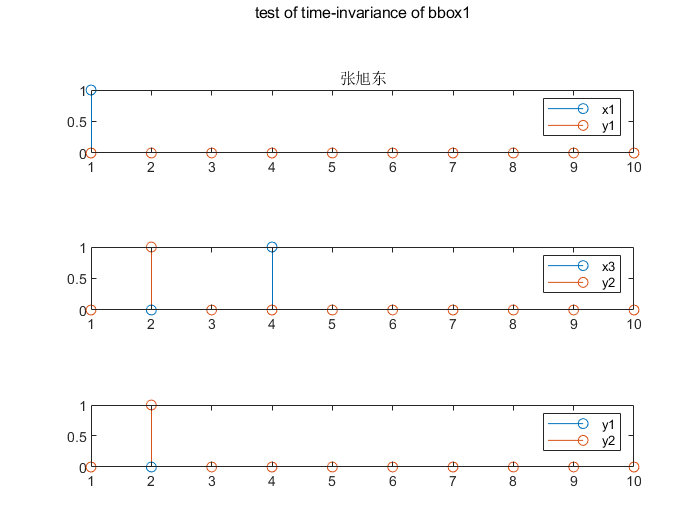

n=0:9;
x1=[1 zeros(1,9)];%x1=delta[n]
x2=cos(0.25*pi.*n);%x2=cos(0.25*pi.*n)
x3=[zeros(1,3) 1 zeros(1,6)];%x1=delta[n]

y1=bbox1(x1);
y2=bbox1(x3);

figure;

subplot(3,1,1);
stem(x1);hold on;
stem(y1);
legend('x1','y1');
title(["test of time-invariance of bbox1" newline '张旭东'])

subplot(3,1,2);
stem(x3);hold on;
stem(y2);
legend('x3','y2');

subplot(3,1,3);
stem(y1);hold on;
stem(y2);
legend('y1','y2');

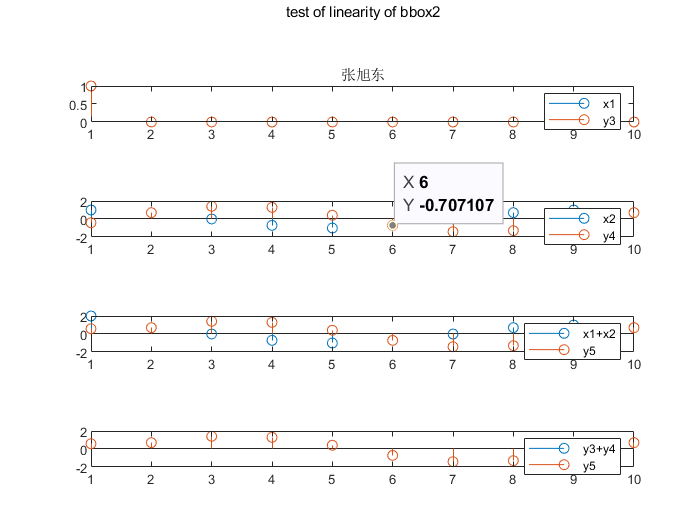



y3=bbox2(x1);
y4=bbox2(x2);
y5=bbox2(x1+x2);

figure;
subplot(4,1,1);
stem(x1);hold on;
stem(y3);
legend('x1','y3');
title(["test of linearity of bbox2" newline '张旭东'])

subplot(4,1,2);
stem(x2);hold on;
stem(y4);
legend('x2','y4');

subplot(4,1,3);
stem(x1+x2);hold on;
stem(y5);
legend('x1+x2','y5');

subplot(4,1,4)
stem(y3+y4);hold on;
stem(y5);
legend('y3+y4','y5');

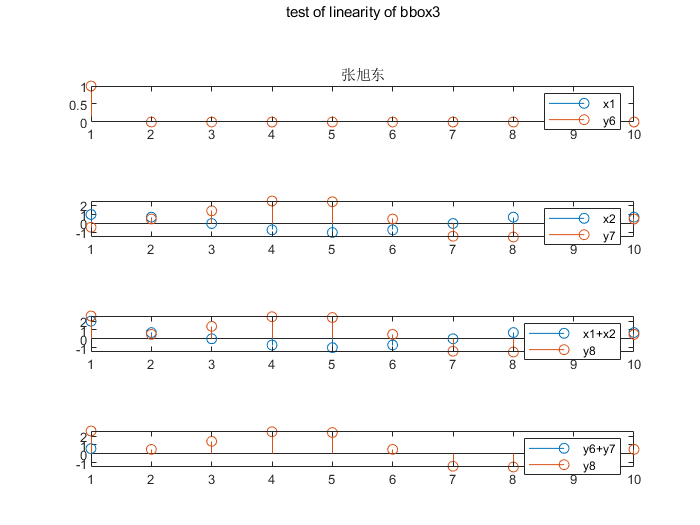



y6=bbox3(x1);
y7=bbox3(x2);
y8=bbox3(x1+x2);

figure;
subplot(4,1,1);
stem(x1);hold on;
stem(y6);
legend('x1','y6');
title(["test of linearity of bbox3" newline '张旭东'])

subplot(4,1,2);
stem(x2);hold on;
stem(y7);
legend('x2','y7');

subplot(4,1,3);
stem(x1+x2);hold on;
stem(y8);
legend('x1+x2','y8');

subplot(4,1,4)
stem(y6+y7);hold on;
stem(y8);
legend('y6+y7','y8');